# ECMOR-2022

## Control blocks

 

slider =100;

dropdown = slider;

check = true;

edit = 0.618 * check * dropdown;



## Introduction

bound = [0,1];

genK = @(N) genField(N+1, 1e-4, 1e-3, 0.1, 0.1); % non-uniform

calcG = @(u) [1 + 0.5 * u.^2, u];

genBC_val = @(N) genField(N+2, 0, 10,0.1, 0.1); % initial and boundary

gen_q_pos = @(k) (-4)^(k) * (rand()-0.5)^(2*k+1)+0.5;

Nt = 1000;

newton_param = struct(...
    'iters'    , 10,...
    'iters_min', 3,...
    'tol'      , 1e-9,...
    'tol_rel'  , 1e-9,...
    'tol_g'    , 1e-4,...
    'tol_rel_g', 1e-4 ...
    );

nlin_newton = @(x,Res,Jac) newton(x,Res,Jac,newton_param);

### FOM

 
Nx = 1000;
dx = 1/Nx;

K = genK(Nx);
q_pos = gen_q_pos(2);
q_val = 1;
U0 = genBC_val(Nx);

D.val = K; D.model = calcG;

BC = genBC(1,[U0(1),U0(end)]);

Q.pos = round(Nx*q_pos); Q.val = sparse(Q.pos,1,q_val,Nx,1);

FOM = genProblem('FOM',Nx,genParam(D,BC,Q),U0(2:end-1));

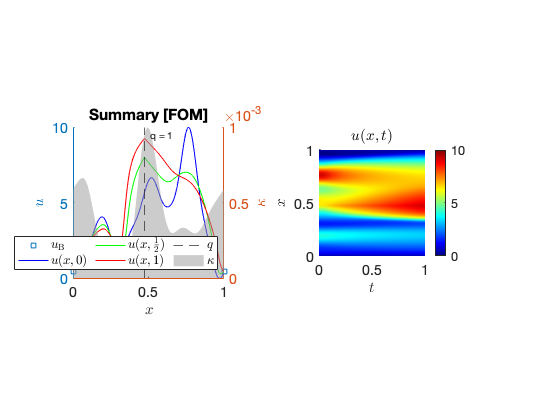

Nt = 100;
FOM = solveDif(1,Nt,FOM, nlin_newton);
plotSol(figure(),FOM,12);

### ROM-I

### ROM-II

### Generalizing ability

#### High

#### Low

## Method 1

### POD basis for different x_q

### Domain decomposition and mapping

### Zero-order approach

### Domain-wise POD performance